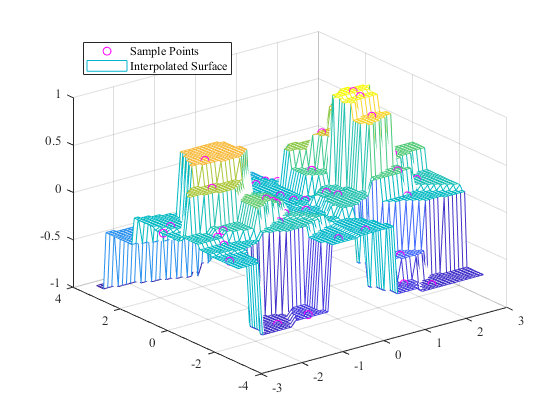

% Create a sample dataset containing 50 random points.
clear all
close all
rng(10) % Initialize the random number generator with a seed of 10
x = -3 + 6*rand(50,1); % Generate random x-coordinates
y = -3 + 6*rand(50,1); % Generate random y-coordinates
v = sin(x).^4 .* cos(y); % Compute the corresponding values

% Create a grid of query points.
[Xq,Yq] = meshgrid(-3:0.1:3);
%vq = sin(Xq).^4 .* cos(Yq)
Vq = NNI(x,y,v,Xq,Yq); % Perform Nearest Neighbor Interpolation (NNI)
plot3(x,y,v,'mo')  % Plot the sample points
hold on
mesh(Xq,Yq,Vq) % Plot the interpolated surface
% title('NNI')
legend('Sample Points','Interpolated Surface',...
    'Location','NorthWest')
set(gca, 'FontName','Times New Roman');
grid on

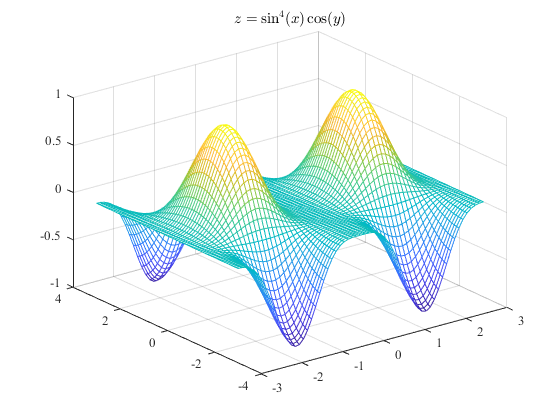


%% Plot the true surface
figure
V = sin(Xq).^4 .* cos(Yq); % Compute the true surface values
mesh(Xq,Yq,V) % Plot the true surface
title('$z=\sin^{4}(x)\cos(y)$','interpreter','latex')
set(gca, 'FontName','Times New Roman');
grid on